# **Create the Ramsey-Cass-Koopmans model using MATLAB**

This example shows how to define and solve the Ramsey-Cass-Koopmans model (a system of coupled ODEs) using MATLAB. Time elimination is used in this example as alternative solution method. This expresses $c$ as a function of $k$ in order to eliminate the time variable.

*Copyright 2016-2025 The MathWorks, Inc.*

## Define the model parameters.

See [`defineRCKParams`](matlab: edit defineRCKParams) for more details.

defineRCKParams

## Define the lower range of $k$-values.

k_steady = params.k_steady;
gap = 1e-2;
k_lower = [10, k_steady - gap];

## Define the upper range of $k$-values.

k_upper = [k_steady + gap, 100];

## Define the initial conditions.

c_lower = 3;
c_upper = c_lower;

## Define the right-hand side of the equations.

See [`RCK_TimeElim`](matlab: edit RCK_TimeElim) for more details.

RCK_Fun = @(k, c) RCK_TimeElim(k, c, params);

## Solve the system using `ode45`.

We use [`ode45`](matlab: doc ode45) to solve the ODEs.

[k_out_lower, c_out_lower] = ode45(RCK_Fun, k_lower, c_lower);
[k_out_upper, c_out_upper] = ode45(RCK_Fun, k_upper, c_upper);

## Visualize the results.

First, plot the numerical solution of the ODE.

figure
plot(k_out_lower, c_out_lower, ".-")
hold on
plot(k_out_upper, c_out_upper, ".-")

Next, add the steady state curves.

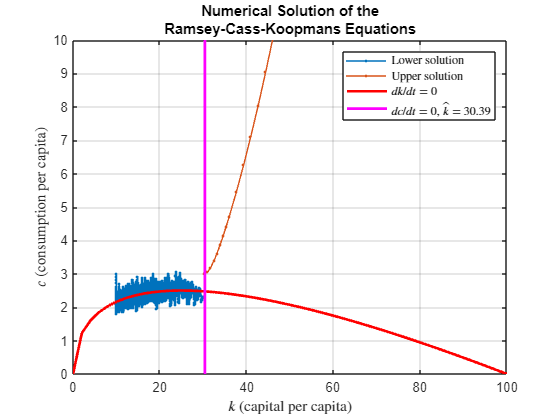

plot(params.k_fine, params.c_star, "r", "LineWidth", 2)
plot([k_steady, k_steady], ylim(), "m", "LineWidth", 2)
hold off
xlabel("$k$ (capital per capita)", "Interpreter", "latex")
ylabel("$c$ (consumption per capita)", "Interpreter", "latex")
title(sprintf("Numerical Solution of the\nRamsey-Cass-Koopmans Equations"))
grid on
ylim([0, 10])
legend(["Lower solution", "Upper solution", ...
    "$dk/dt = 0$", "$dc/dt=0$, $\hat{k}$ = " + num2str(k_steady, "%.2f")], ...
        "Interpreter", "latex")

## Solve the lower system using a stiff solver.

See [`RCK_Jacobian`](matlab: edit RCK_Jacobian) for more details. We use the stiff solver [`ode15s`](matlab: doc ode15s) on this system.

J = @(k, c) RCK_Jacobian(k, c, params);
opts = odeset("Jacobian", J);
warningID = "MATLAB:ode15s:IntegrationTolNotMet";
warningStatus = warning("query", warningID);
warning("off", warningID)
[k_out_lower, c_out_lower] = ode15s(RCK_Fun, k_lower, c_lower);
warning(warningStatus)

## Plot the numerical solution of the ODE.

figure
plot(k_out_lower, c_out_lower, ".-")
axLims = axis();
hold on

Next, add the steady state curves.

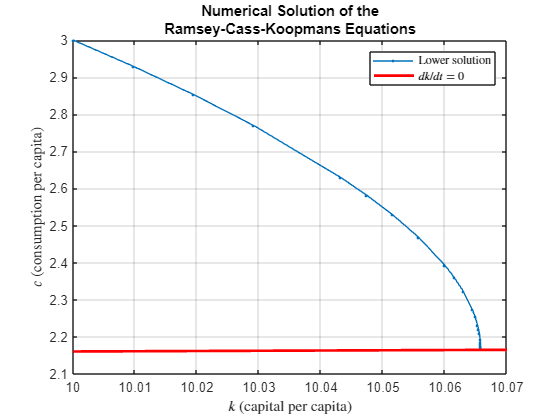

plot(params.k_fine, params.c_star, "r", "LineWidth", 2)
hold off
xlabel("$k$ (capital per capita)", "Interpreter", "latex")
ylabel("$c$ (consumption per capita)", "Interpreter", "latex")
title(sprintf("Numerical Solution of the\nRamsey-Cass-Koopmans Equations"))
grid on
axis(axLims)
legend(["Lower solution", "$dk/dt = 0$"], "Interpreter", "latex")